clc
clearvars
close all

nlist = readtable("./data/nlist.csv");
nlist.Properties.VariableNames = {'Name','Label','Group'};
nlist.Name = string(nlist.Name);
elist_dy = readtable("./data/elist_dynamic.csv");

node_cdata = NaN(size(nlist,1),3);
node_group = unique(nlist.Group);
ccode = NaN(length(node_group),3);
ccode(1,:) = [1, 0, 0];
ccode(2,:) = [0, 0, 1];
for i=1:length(node_group)
    idx = find(strcmp(nlist.Group, node_group{i}));
    node_cdata(idx,:) = repmat(ccode(i,:),length(idx),1);
end

# Dynamic network

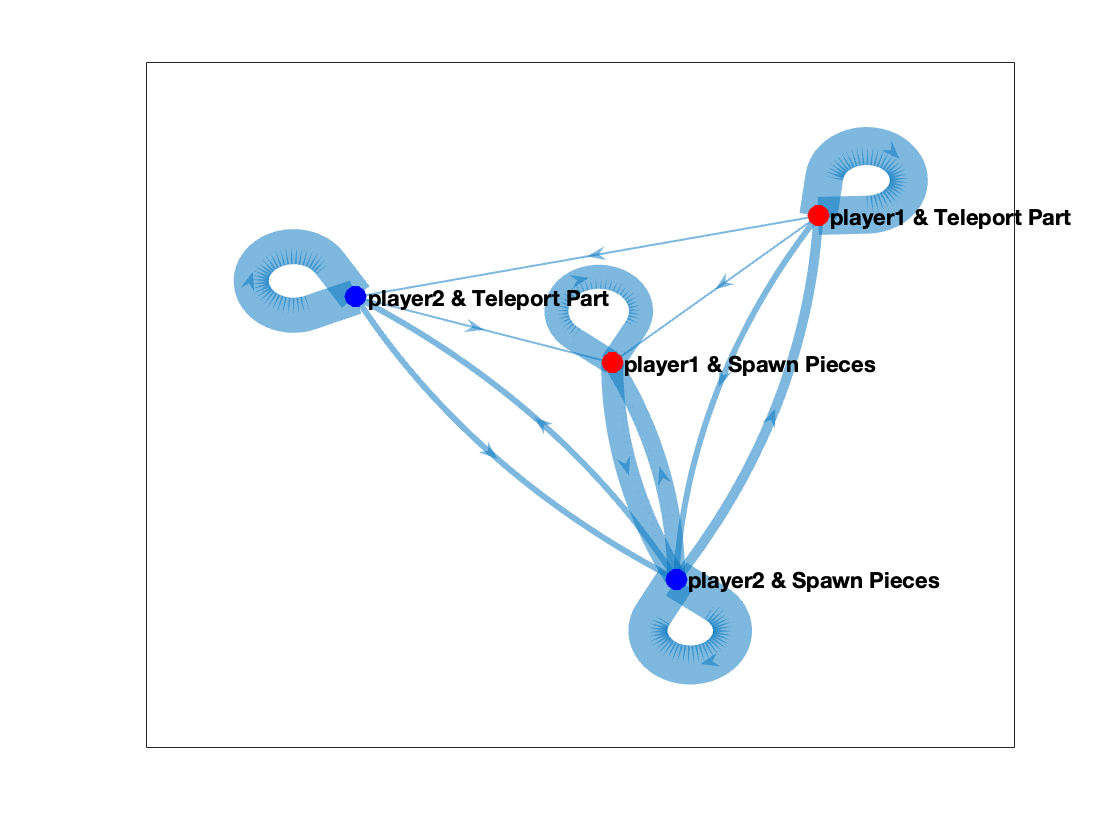

num_nodes = size(nlist,1);
num_edges = size(elist_dy,1);
snodes = elist_dy.Source;
tnodes = elist_dy.Target;
edge_weight_cutoff = 16;

s = snodes(1);
t = tnodes(1);
elist = [s,t];
w = 1;
etable = table(elist,w, 'VariableNames',{'EndNodes','Weight'});
G = digraph(etable,nlist);

figure('Color','w')
for i=2:num_edges
    s = snodes(i);
    t = tnodes(i);
    [edge_exist,update_idx] = ismember([s,t],str2double(G.Edges.EndNodes),'rows');

    if(all(edge_exist))
        w = G.Edges.Weight;
        if(w(update_idx) >= edge_weight_cutoff)
            G.Edges.Weight(update_idx) = w(update_idx) + (0.5)^(w(update_idx)-edge_weight_cutoff+1);
        else
            G.Edges.Weight(update_idx) = w(update_idx)+1;
        end
    else
        G = addedge(G,num2str(s),num2str(t),1);
    end

    plot(G,'NodeLabel',nlist.Label,'NodeColor',node_cdata,'MarkerSize',10,...
        'NodeFontSize',11,'NodeFontWeight','bold',...
        'LineWidth',G.Edges.Weight,'Layout','force')
    drawnow
end

wsaved = G.Edges.Weight;

# Centrality measures of nodes

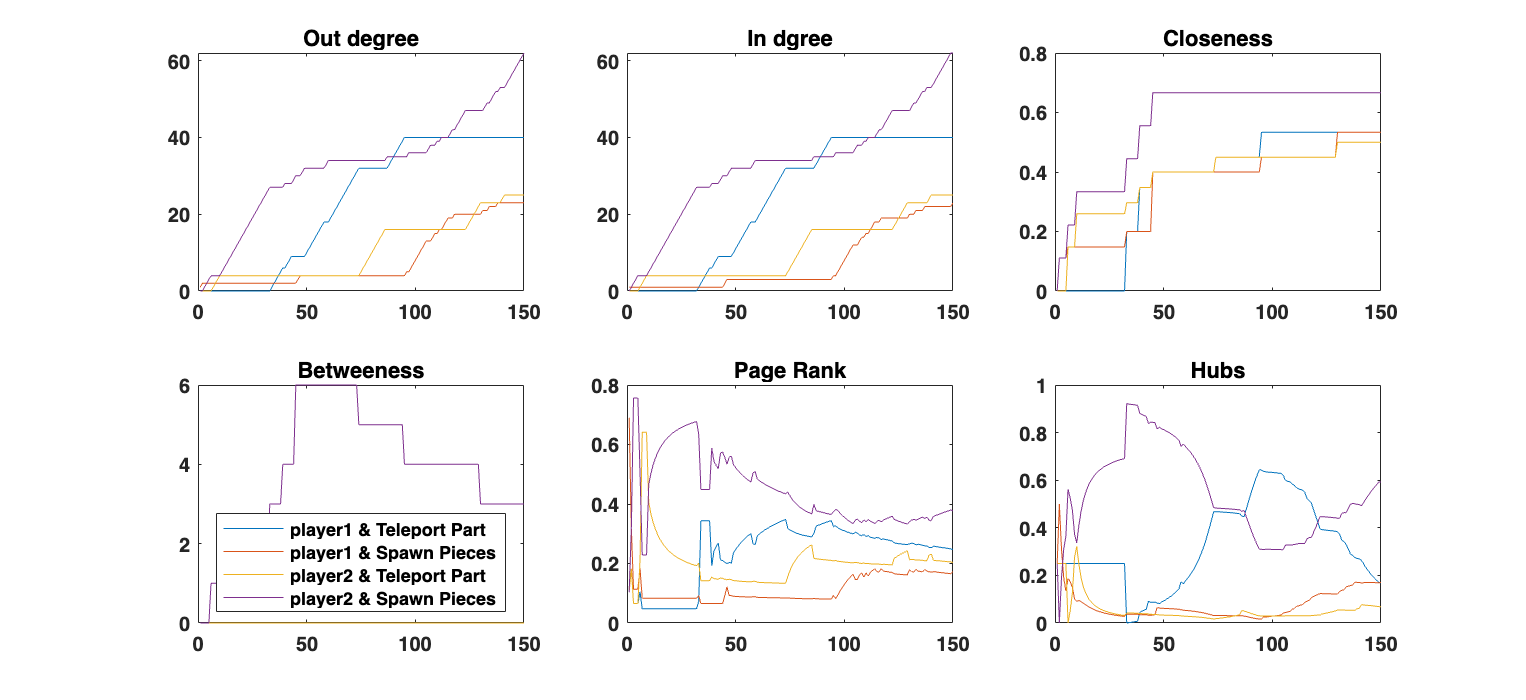

s = snodes(1);
t = tnodes(1);
elist = [s,t];
etable = table(elist,1, 'VariableNames',{'EndNodes','Weight'});

od = zeros(num_edges,num_nodes);
id = zeros(num_edges,num_nodes);
oc = zeros(num_edges,num_nodes);
ic = zeros(num_edges,num_nodes);
btw = zeros(num_edges,num_nodes);
pr = zeros(num_edges,num_nodes);
h = zeros(num_edges,num_nodes);

G = digraph(etable,nlist);

od(1,:) = centrality(G,'outdegree','Importance',G.Edges.Weight);
id(1,:) = centrality(G,'indegree','Importance',G.Edges.Weight);
oc(1,:) = centrality(G,'outcloseness');
ic(1,:) = centrality(G,'incloseness');
btw(1,:) = centrality(G,'betweenness');
pr(1,:) = centrality(G,'pagerank','Importance',G.Edges.Weight);
h(1,:) = centrality(G,'hubs','Importance',G.Edges.Weight);

for i=2:num_edges
    s = snodes(i);
    t = tnodes(i);
    [edge_exist,update_idx] = ismember([s,t],str2double(G.Edges.EndNodes),'rows');

    if(all(edge_exist))
        G.Edges.Weight(update_idx) = G.Edges.Weight(update_idx)+1;
    else
        G = addedge(G,num2str(s),num2str(t),1);
    end
    
    od(i,:) = centrality(G,'outdegree','Importance',G.Edges.Weight);
    id(i,:) = centrality(G,'indegree','Importance',G.Edges.Weight);
    oc(i,:) = centrality(G,'outcloseness');
    ic(i,:) = centrality(G,'incloseness');
    btw(i,:) = centrality(G,'betweenness');
    pr(i,:) = centrality(G,'pagerank','Importance',G.Edges.Weight);
    h(i,:) = centrality(G,'hubs','Importance',G.Edges.Weight);
end

figure('Color','w','Position',[0,0,1200,550])
subplot(2,3,1)
plot(od)
title("Out degree")
set(gca,'FontWeight','bold')

subplot(2,3,2)
plot(id)
title("In dgree")
set(gca,'FontWeight','bold')

subplot(2,3,3)
plot(oc+ic)
title("Closeness")
set(gca,'FontWeight','bold')

subplot(2,3,4)
plot(btw)
title("Betweeness")
legend(string(nlist.Label),'Location','south')
set(gca,'FontWeight','bold')

subplot(2,3,5)
plot(pr)
title("Page Rank")
set(gca,'FontWeight','bold')

subplot(2,3,6)
plot(h)
title("Hubs")
set(gca,'FontWeight','bold')